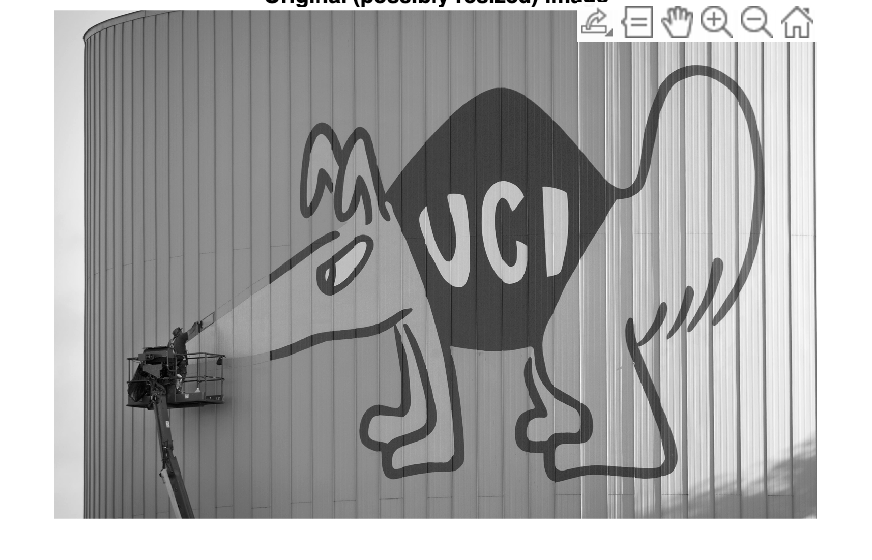

%% Lab 8: Main File
% In this lab, you will generate a compressed version of your image of
% choice (inappropriate images will result in a 0 scored lab that cannot be
% dropped).
clear; clc; close all;

%% Part 1: Load an image into Matlab as a matrix A

img = imread('anteater.jpg');

% (If the image is RGB, convert to grayscale, I just chose the direct
% grayscale image!)
if ndims(img) == 3
    img = rgb2gray(img);
end

% Scale image down so that max dimension < or = 1500 as instructions say
[m0, n0] = size(img);
max_dim = max(m0, n0);
if max_dim > 1500
    scale = 1500 / max_dim;
    img = imresize(img, scale);
end

% Convert to double in [0,1]
A = im2double(img);
[m, n] = size(A);

figure;
imshow(A, []);
title('Original (possibly resized) image');

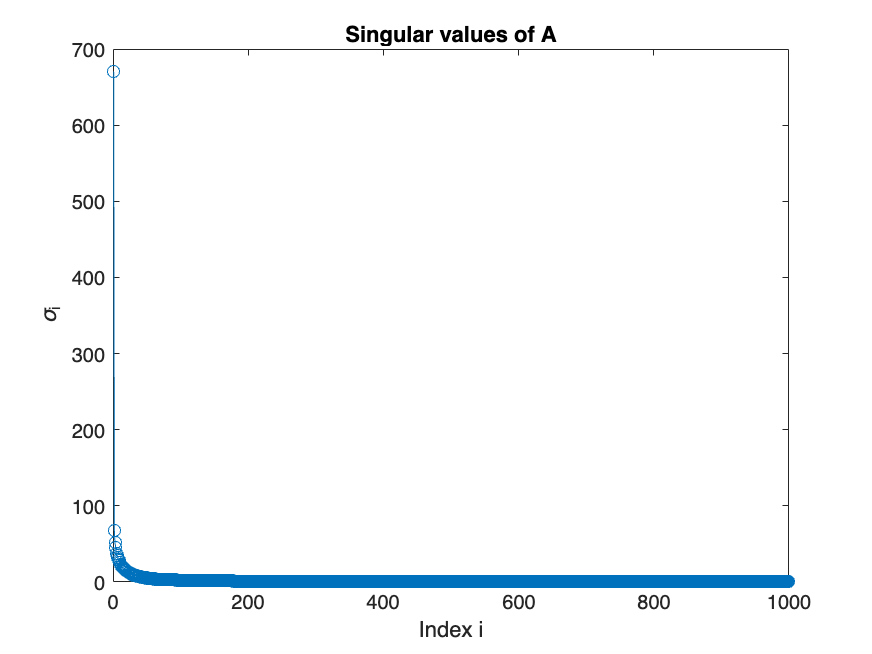



%% Part 2: Apply SVD to the image and plot singular values

[U, S, V] = svd(A, 'econ');          % A ≈ U*S*V'
sing_vals = diag(S);

figure;
plot(sing_vals, 'o-');
xlabel('Index i');
ylabel('\sigma_i');
title('Singular values of A');

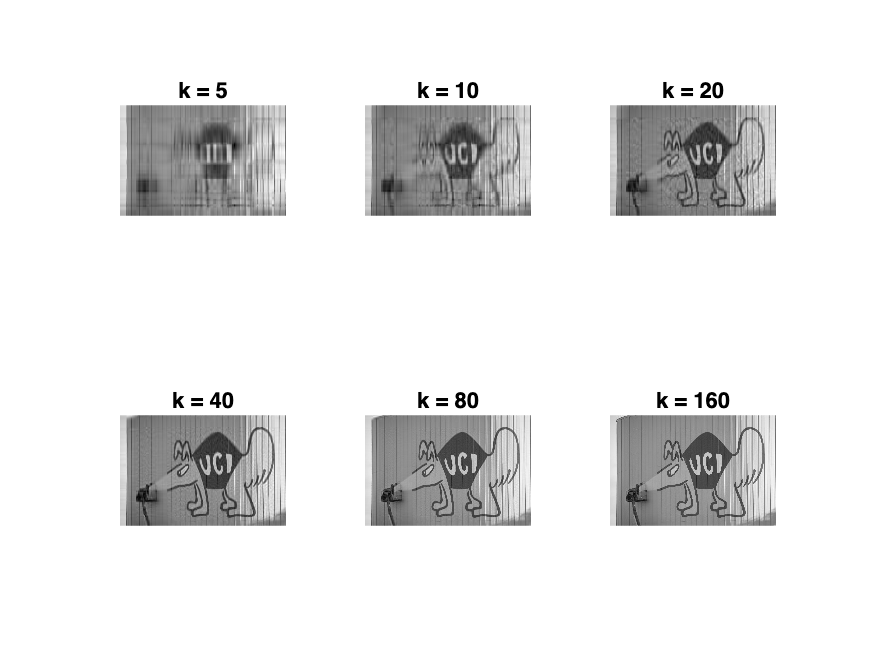



%% Part 3: Visualize compressed images
% The rank k approximation of A is sum_{i=1}^k U(:,i) * S(i,i) * V(:,i)'

% Choose some k values to visualize
k_values = [5 10 20 40 80 160];
k_values = k_values(k_values <= length(sing_vals)); 
num_k = numel(k_values);

figure;
for j = 1:num_k
    k = k_values(j);
    Ak = U(:,1:k) * S(1:k,1:k) * V(:,1:k)';   % rank-k approximation

    subplot(2, ceil(num_k/2), j);
    imshow(Ak, []);
    title(sprintf('k = %d', k));
end

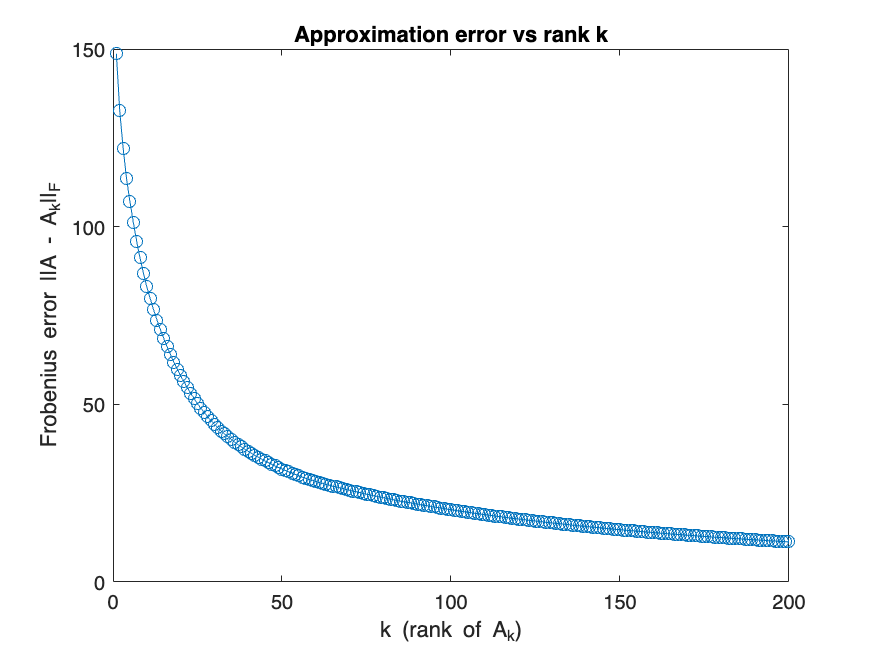



%% Part 4: Plot r v.s. low rank approximation error

% Use Frobenius norm of (A - A_k) as the error measure
kmax = min(200, length(sing_vals));  
errors = zeros(1, kmax);

for k = 1:kmax
    Ak = U(:,1:k) * S(1:k,1:k) * V(:,1:k)';
    errors(k) = norm(A - Ak, 'fro');          % absolute error
end

figure;
plot(1:kmax, errors, '-o');
xlabel('k (rank of A_k)');
ylabel('Frobenius error ||A - A_k||_F');
title('Approximation error vs rank k');

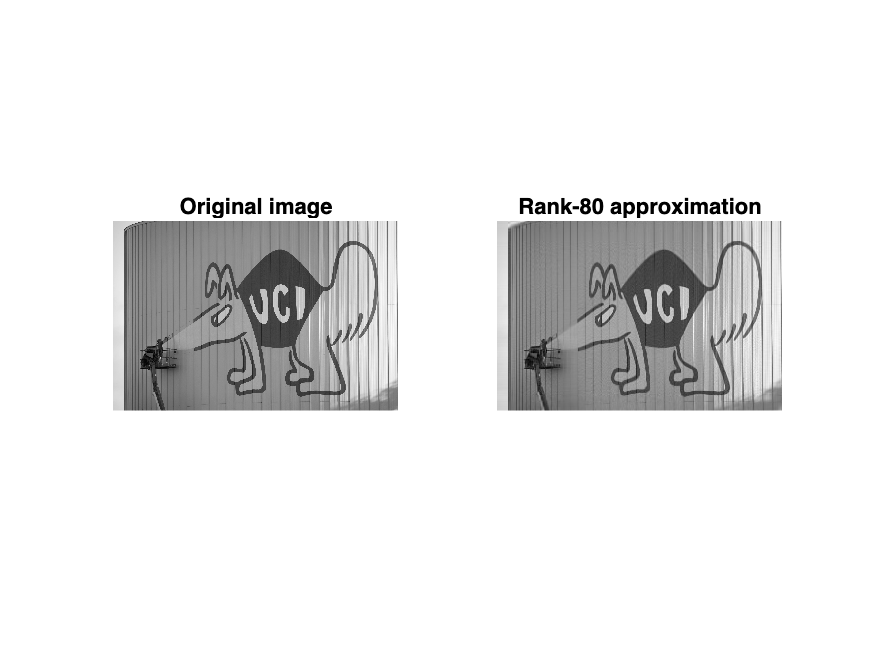



%% Part 5: Plot original image and best compression
% The compression ratio represents how much the image has been compressed.
% If an image originally needs mn elements for storage, its rank k
% approximation needs mr + r + nr elements. The compression ratio is
% mn/(mr + r + nr) = mn/(r(m + 1 + n)).

% Choose k_best based on what still looks recognizable
% After looking at the images and error plot, change this number if needed.
k_best = 80;             
k_best = min(k_best, length(sing_vals));

A_best = U(:,1:k_best) * S(1:k_best,1:k_best) * V(:,1:k_best)';

figure;
subplot(1,2,1);
imshow(A, []);
title('Original image');

subplot(1,2,2);
imshow(A_best, []);
title(sprintf('Rank-%d approximation', k_best));


% Compute and display the compression ratio
r = k_best;
compression_ratio = (m * n) / (r * (m + 1 + n));
fprintf('Image size: %d x %d\n', m, n);

Image size: 1000 x 1500


fprintf('For k = %d, compression ratio = %.2f\n', r, compression_ratio);

For k = 80, compression ratio = 7.50
